clc
clear all

c = 3*10^8; 
lambda0 = 800*10^-9;
f0 = c/lambda0;
L = .5; % Length of cavity is 50 cm
R = .9; % Default reflectivity is 90%
n = 1; 
FSR = c/(2*n*L); % free spectral range of cavity
k0 = 2*pi*n/lambda0;

**a)**

First, the free spectral range (FSR) is given as: $\textrm{FSR}=\frac{c}{2\textrm{nL}}=\frac{c}{2L}\;\left(\textrm{for}\;n=1\right)$.  

The transmittance of the light in the cavity is given by: 

$T=\frac{\left(1-R_1 \right)\left(1-R_2 \right)}{{\left(1-\sqrt{R_1 R_2 }\right)}^2 +4\sqrt{R_1 R_2 }\sin^2 \left(\textrm{kL}\right)}$, which for equal reflectivities leads to: 

$T=\frac{{\left(1-R\right)}^2 }{{\left(1-R\right)}^2 +4{\textrm{Rsin}}^2 \left(\textrm{kL}\right)}$.  In this equation, $\textrm{kL}$ is the phase term for propagation over the length L of the cavity, whereas the round trip phase shift would be represented by $2\textrm{kL}$

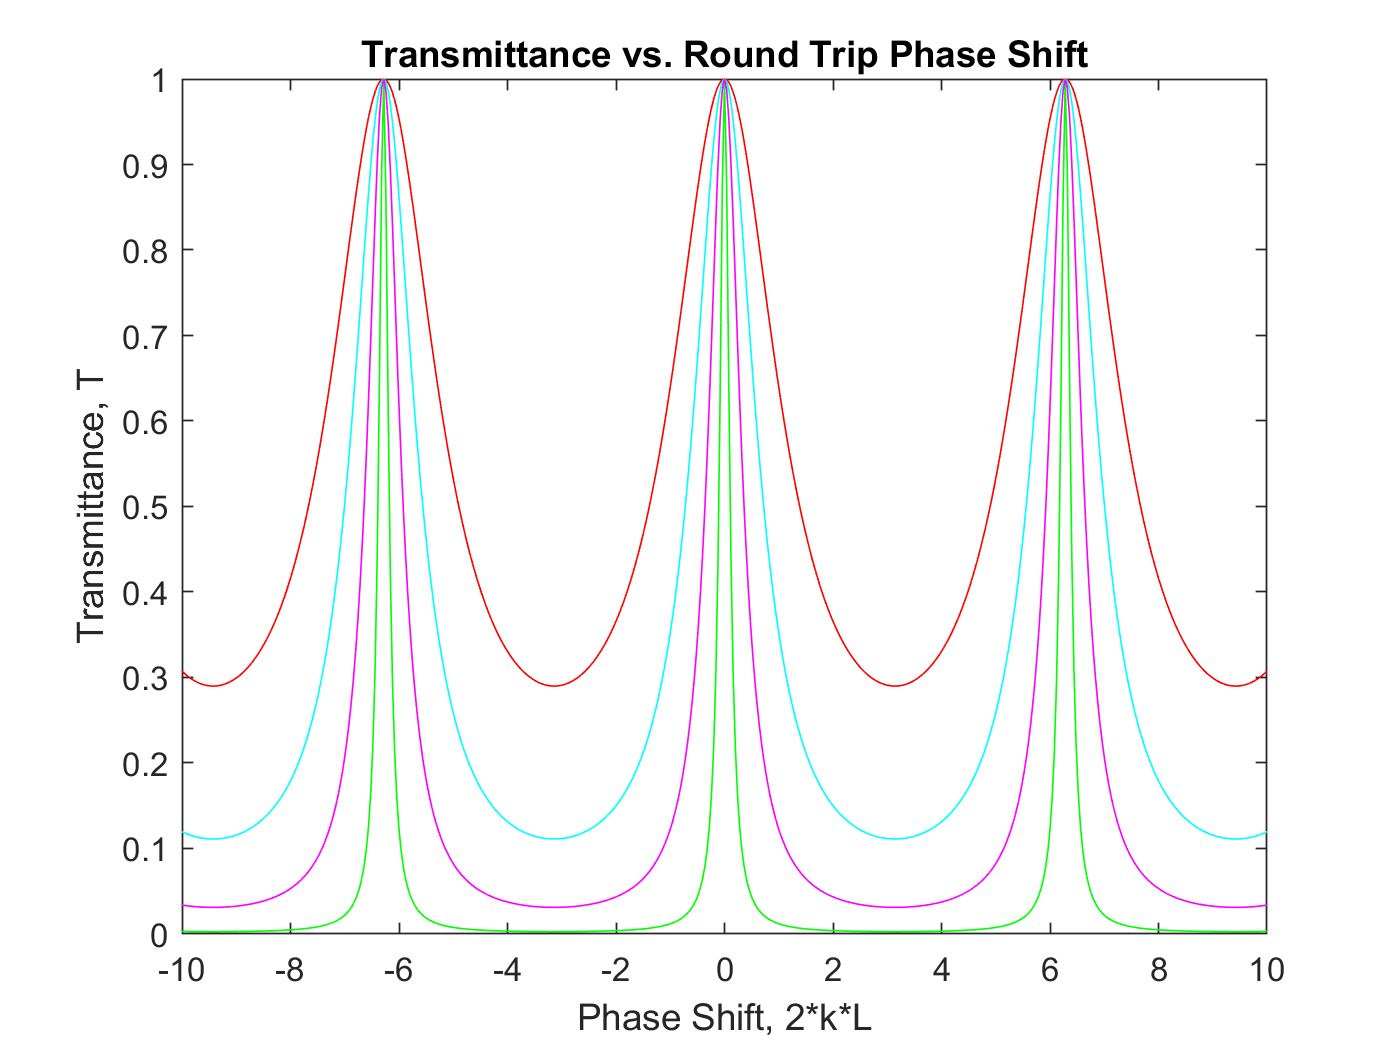

rt_phase = -10:.04:10; % creation of phase sweep variable
T1 = (1-R)^2./((1-R)^2+4*R.*(sin(rt_phase/2).^2)); % Transmittance for R = 90%
R = .3;
T2 = (1-R)^2./((1-R)^2+4*R.*(sin(rt_phase/2).^2)); % "  " for R = 30%
R = .5; 
T3 = (1-R)^2./((1-R)^2+4*R.*(sin(rt_phase/2).^2)); % "  " for R = 50%
R = .7;
T4 = (1-R)^2./((1-R)^2+4*R.*(sin(rt_phase/2).^2)); % "  " for R = 70%

plot(rt_phase,T1,'g',rt_phase,T2,'r',rt_phase,T3,'c',rt_phase,T4,'m')
xlabel('Phase Shift, 2*k*L')
ylabel('Transmittance, T')
title('Transmittance vs. Round Trip Phase Shift')

**b)**

Next, the mode number for the center wavelength of the cavity is

$m=\frac{2\textrm{nL}}{\lambda }$, and the precise mode wavelength is given by: $\lambda_m =\frac{2\textrm{nL}}{m}$.  This gives a corresponding frequency of $\upsilon_m =\frac{c}{\lambda_m }$.  From this, we can find the free spectral range (FSR), or the separation between adjacent modes, $v_m -v_{m-1} =v_f =\frac{c}{2\textrm{nL}}$.  The cavity finesse is $F=\frac{{\pi R}^{\frac{1}{2}} }{1-R}\textrm{or}\;\textrm{alternatively},\frac{v_f }{\delta v_m }$, where $\delta v_m$ is the spectral width, or FWHM of the spectrum.  This leads to the relation $\delta v_m =\frac{v_f }{F}$.  Once we have the free spectral range and FWHM, we can determine the quality factor, Q: $Q=\frac{v_0 }{\delta v_m },\textrm{where}\;v_0 =\frac{c}{\lambda_0 }\;\left(\textrm{the}\;\textrm{center}\;\textrm{frequency}\right)$

 R = .3:.01:.99; % Reflectivity changes from 30% to 99% 
 m = 2*n*L/lambda0; % mode number corresponding to 800 nm
 lambda_m = 2*n*L/m;
 v_m = c/lambda_m

v_m = 3.7500e+14

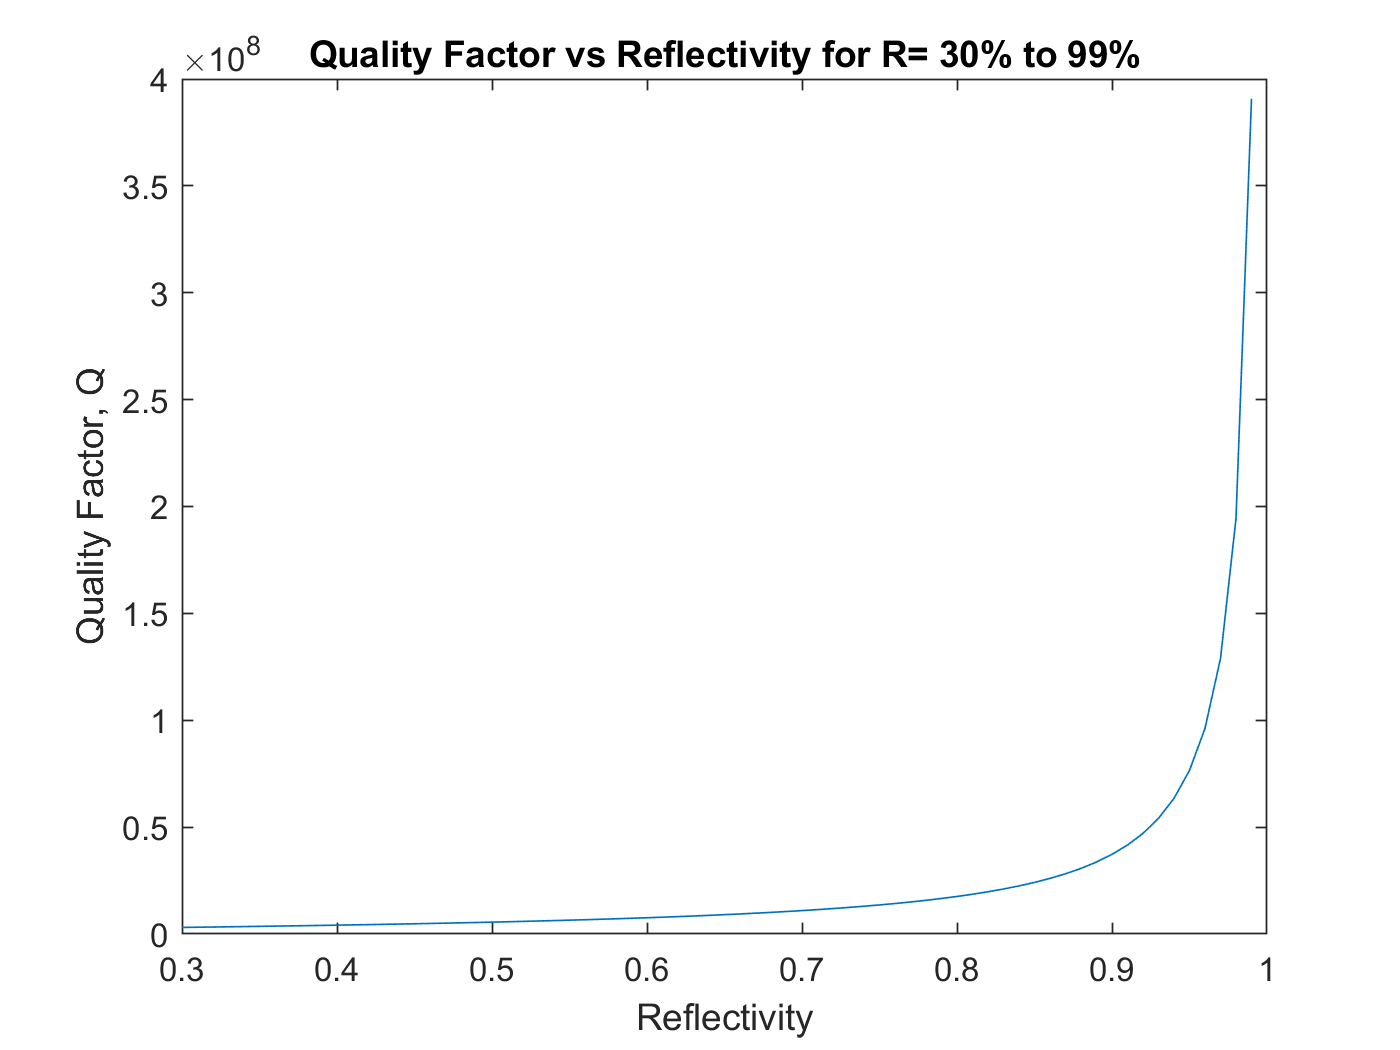

 FSR = c/(2*n*L); % free spectral range
 F = pi.*R.^(1/2)./(1-R);
 dv_m = FSR./F; % Spectral width 
 Q = f0./dv_m;
 plot(R,Q)
 xlabel('Reflectivity')
 ylabel('Quality Factor, Q')
 title('Quality Factor vs Reflectivity for R= 30% to 99%')

**c)**

When propagation loss is factored into the transmitted spectrum for the cavity, the equation for transmittance becomes: 

$T=\frac{e^{-2\alpha L} \left(1-R_1 \right)\left(1-R_2 \right)}{{\left(1-e^{-2\alpha L} \sqrt{R_1 R_2 }\right)}^2 +4e^{-2\alpha L} \sqrt{R_1 R_2 }\sin^2 \left(\textrm{kL}\right)}=\frac{{e^{-2\alpha L} \left(1-R\right)}^2 }{{\left(1-e^{-2\alpha L} R\right)}^2 +4e^{-2\alpha L} {\textrm{Rsin}}^2 \left(\textrm{kL}\right)}$, for $R_1 =R_2 =R$

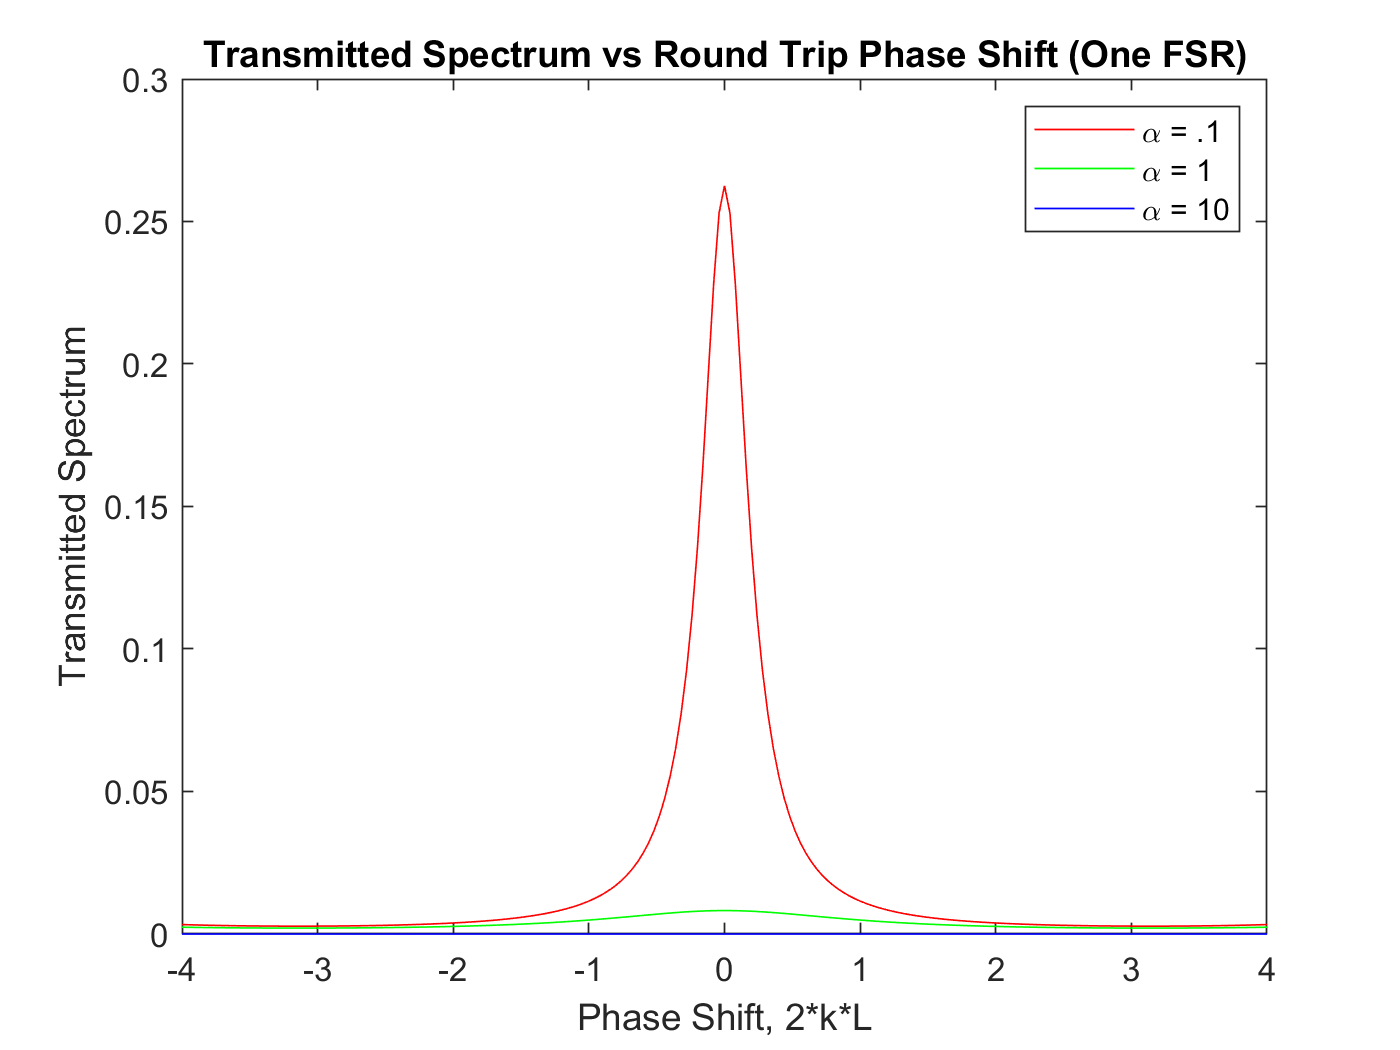

 rt_phase = -4:.04:4;
 R = .9; % Reflectivity back to 90%
 alpha1 = .1; % Propagation loss in m^-1
 alpha2 = 1; 
 alpha3 = 10;
 
 T1 = exp(-2*alpha1*L)*(1-R)^2./((1-exp(-2*alpha1*L)*R)^2+4*exp(-2*alpha1*L)*R.*(sin(rt_phase./2).^2));
 T2 = exp(-2*alpha2*L)*(1-R)^2./((1-exp(-2*alpha2*L)*R)^2+4*exp(-2*alpha2*L)*R.*(sin(rt_phase./2).^2));
 T3 = exp(-2*alpha3*L)*(1-R)^2./((1-exp(-2*alpha3*L)*R)^2+4*exp(-2*alpha3*L)*R.*(sin(rt_phase./2).^2));

 plot(rt_phase,T1,'r',rt_phase,T2,'g',rt_phase,T3,'b')
 xlabel('Phase Shift, 2*k*L')
 ylabel('Transmitted Spectrum')
 title('Transmitted Spectrum vs Round Trip Phase Shift (One FSR)')
 legend('\alpha = .1','\alpha = 1','\alpha = 10')

The transmitted spectrum for a loss coefficient of 10/m is shown again separately, since it's intensity is minute compared to the spectrums corresponding to losses of .1 and 1

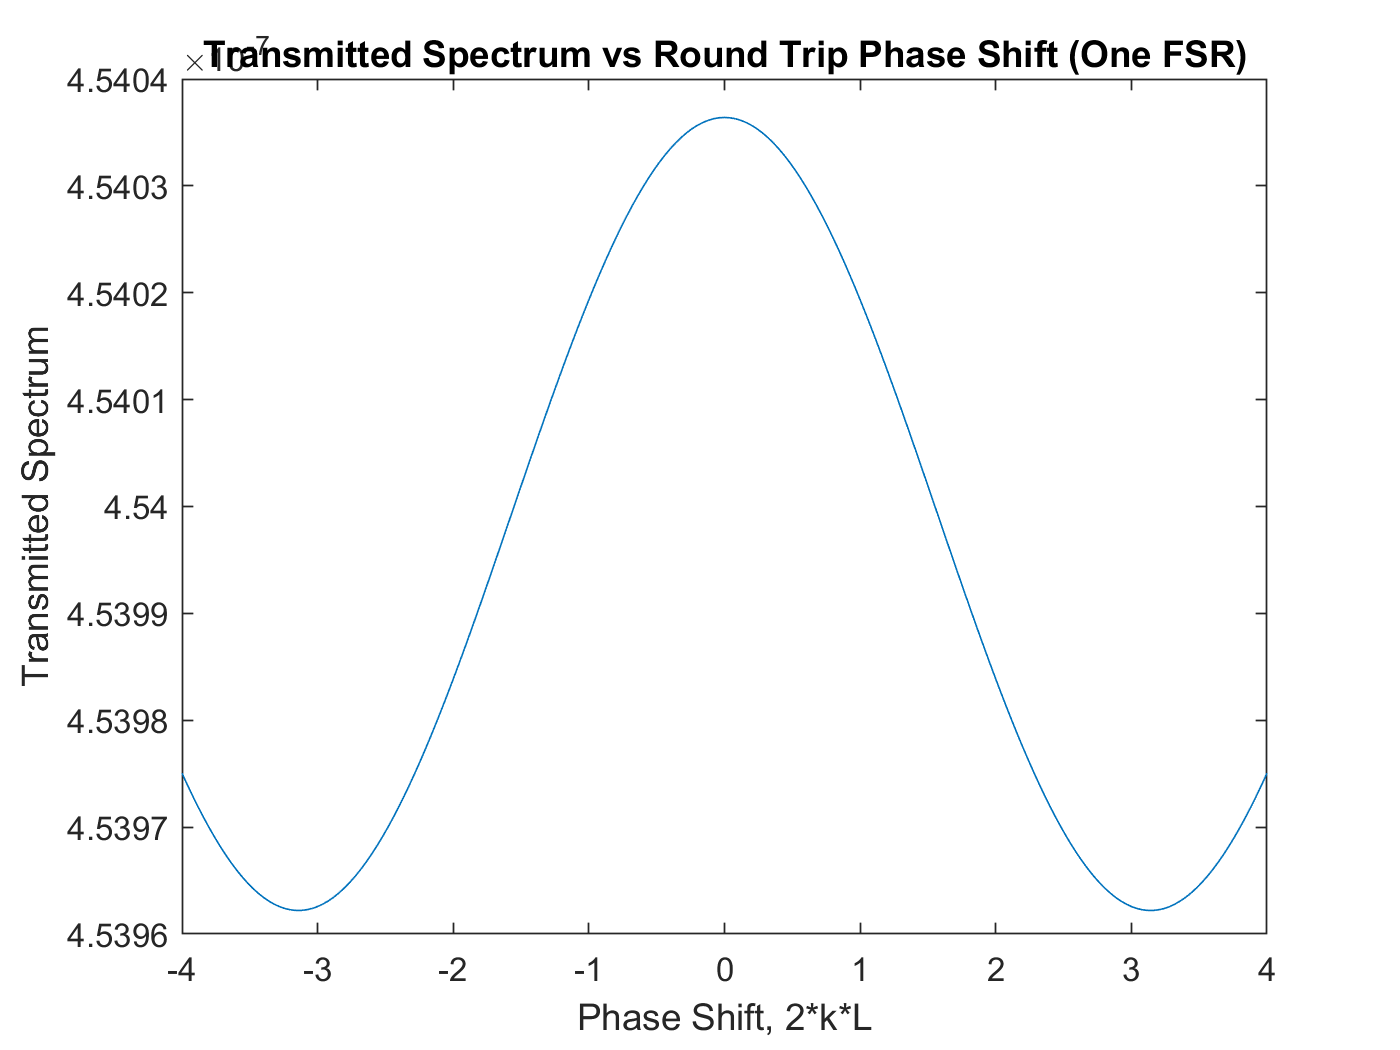

 plot(rt_phase,T3)
 xlabel('Phase Shift, 2*k*L')
 ylabel('Transmitted Spectrum')
 title('Transmitted Spectrum vs Round Trip Phase Shift (One FSR)')

**d)**

By changing the length of the cavity, the free spectral range is altered.  We can see that for a longer cavity, as in the 50 cm length below, higher order modes resonate (which corresponds to a smaller FSR), whereas lower order resonate for the 30 cm cavity.  We also notice the intensity peaks are sharper (lower spectral width) for a greater length. 

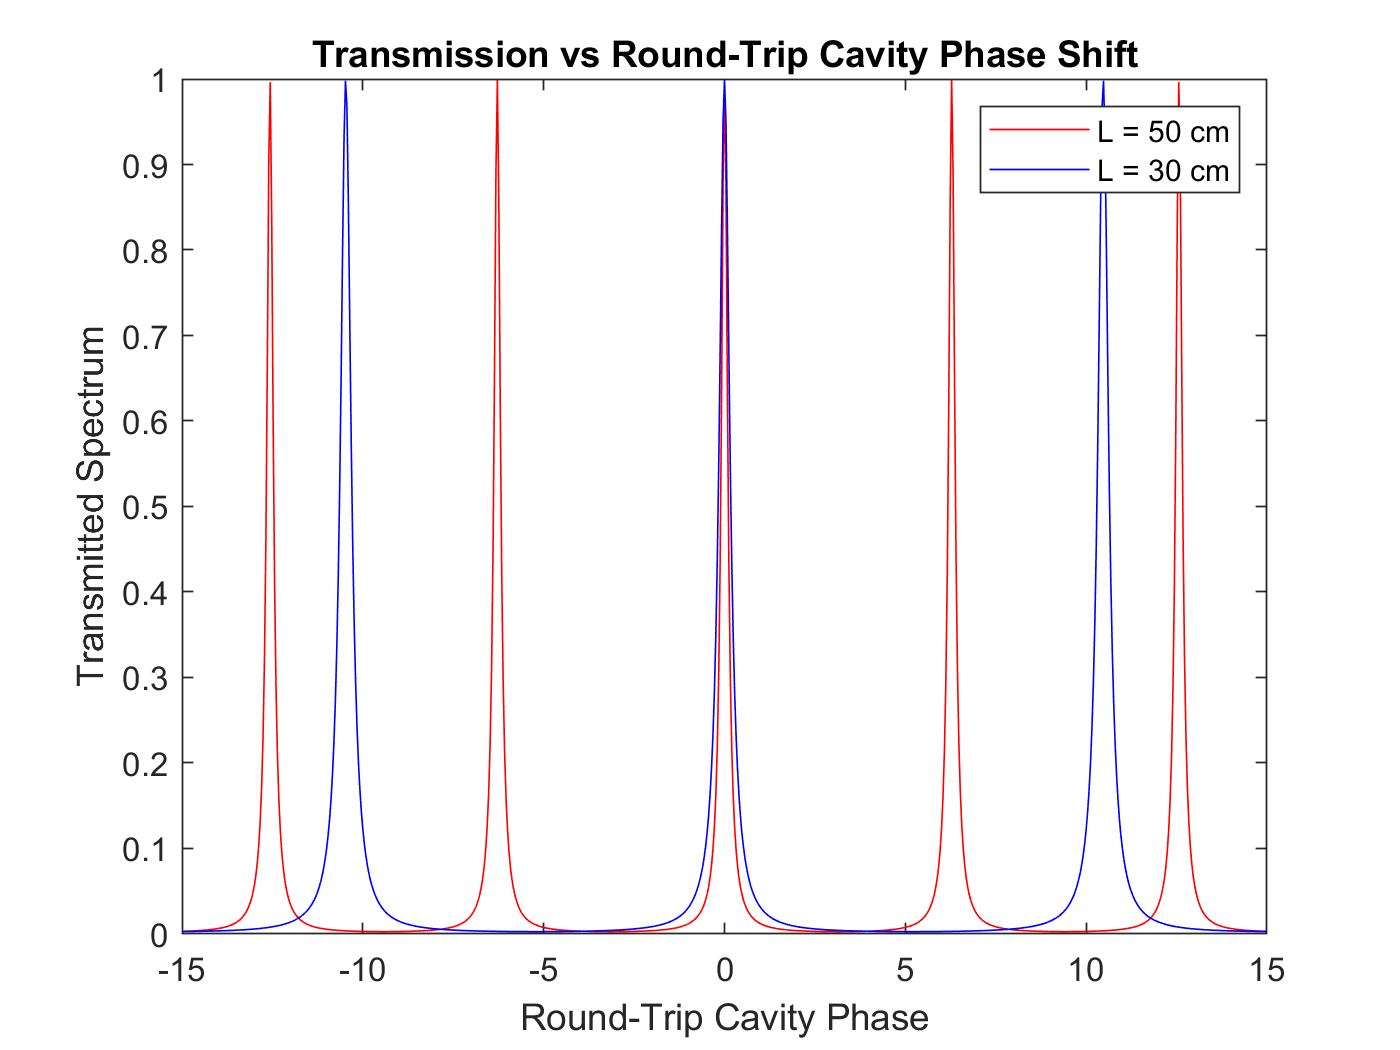

 k = -15:.04:15;
 m = -15:.04:15;
 L1 = .5;
 L2 = .3;
 T1 = (1-R)^2./((1-R)^2+4*R.*(sin(k.*L1).^2)); % Transmission for L = 50 cm
 T2 = (1-R)^2./((1-R)^2+4*R.*(sin(k.*L2).^2)); % Transmission for L = 30 cm
 plot(m,T1,'r',m,T2,'b')
 xlabel('Round-Trip Cavity Phase')
 ylabel('Transmitted Spectrum')
 title('Transmission vs Round-Trip Cavity Phase Shift')
 legend('L = 50 cm','L = 30 cm')

**e)**

When the temperature is shifted, two different effects occur in the cavity: 1) A thermal expansion of materials, and 2) temperature dispersion, or a change of the refractive index of the material with respect to temperature. The free spectral range is now temperature-dependent: 

$\textrm{FSR}=\frac{c}{2\left(n+\frac{\delta n}{\textrm{dT}}\Delta T\right)L\left(1+\gamma \Delta T\right)}\;,\textrm{where}\;\frac{\delta n}{\delta T}=\frac{{10}^{-4} }{C}\;\textrm{and}\;\gamma =\frac{1}{L}\frac{\textrm{dL}}{\textrm{dT}}=9*\frac{{10}^{-6} }{C}$, which are the temperature refractive index and thermal expansion coefficients, respectively.  The previously used round-trip phase term is multiplied by a term with a modified refractive index and thermal expansion taken into effect.  It is clear that for higher temperatures, the free spectral range is smaller.  Thus, the curves corresponding to 100 and 50 degrees are shifted to the left relative to the 20 degree transmission spectrum.

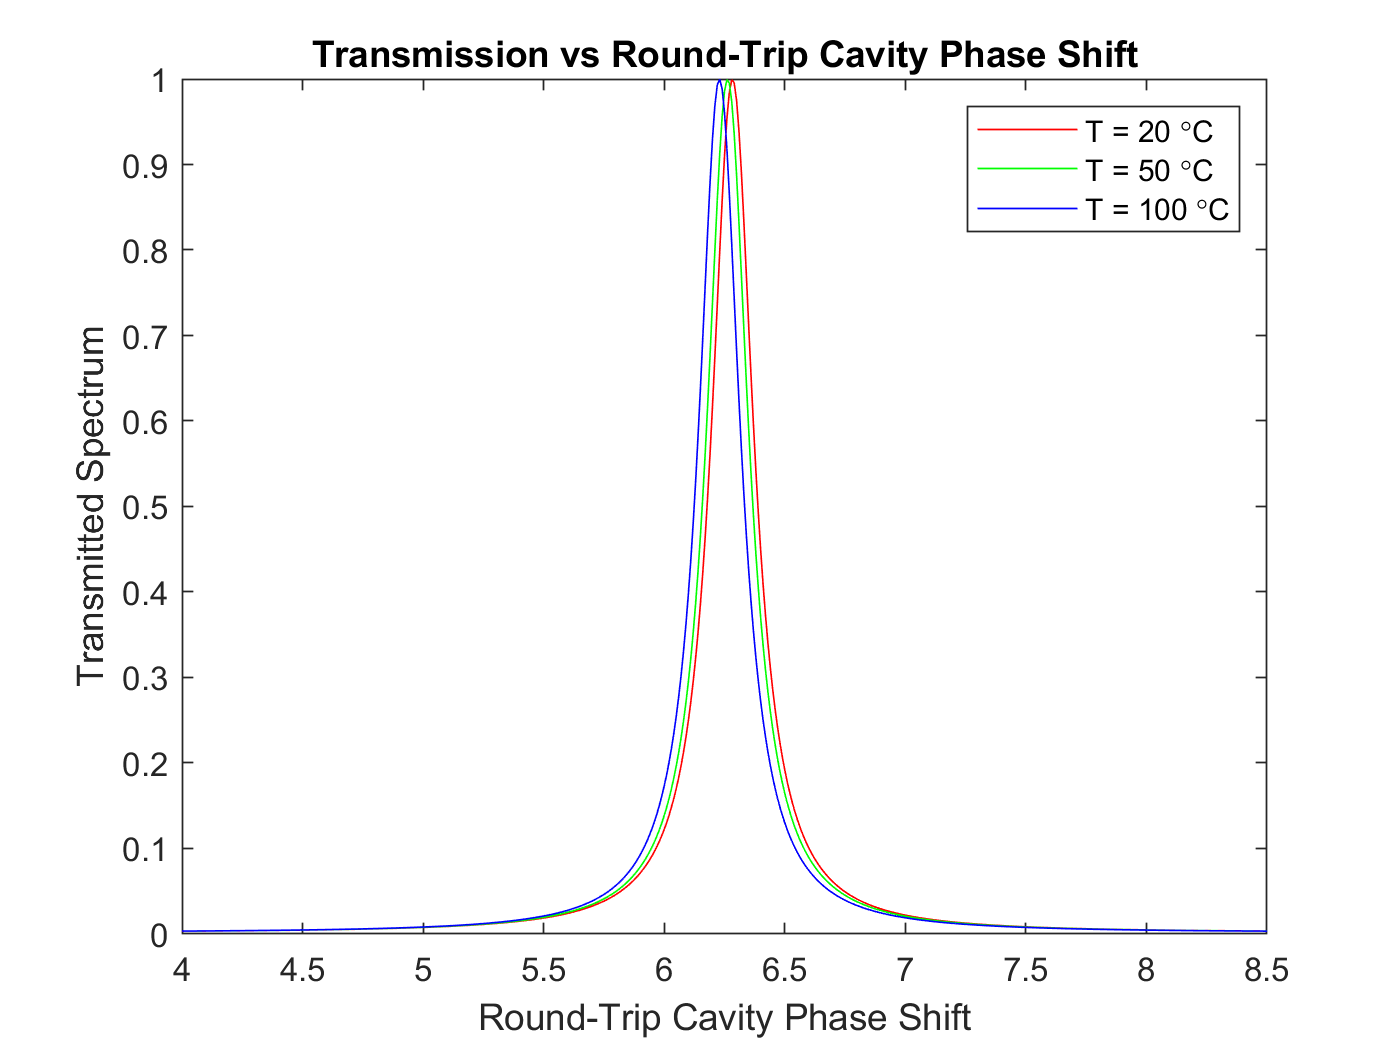

 gamma = 9*10^-6; % thermal expansion coefficient
 dn_dT = 10^-4; % temperature dispersion coefficient 
 dT1 = 0;
 dT2 = 30; 
 dT3 = 80;
 phase_1 = (n+dn_dT*dT1)*(1+gamma*dT1); % modified phase for T = 20 C
 phase_2 = (n+dn_dT*dT2)*(1+gamma*dT2); % "     " for T = 50 C
 phase_3 = (n+dn_dT*dT3)*(1+gamma*dT3); % "     " for T = 100 C
 
 rt_phase = -10:.01:10;
 
 T1 = (1-R)^2./((1-R)^2+4*R.*(sin(rt_phase*phase_1/2).^2)); % Transmission for 20 degrees (room temp)
 T2 = (1-R)^2./((1-R)^2+4*R.*(sin(rt_phase*phase_2/2).^2)); % "     " for 50 degrees 
 T3 = (1-R)^2./((1-R)^2+4*R.*(sin(rt_phase*phase_3/2).^2)); % "     " for 100 degrees
 plot(rt_phase,T1,'r',rt_phase,T2,'g',rt_phase,T3,'b')
 title('Transmission vs Round-Trip Cavity Phase Shift')
 xlabel('Round-Trip Cavity Phase Shift')
 ylabel('Transmitted Spectrum')
 legend('T = 20 \circC','T = 50 \circC','T = 100 \circC')
 xlim([4 8.5])